Plot settings

cMap=[0.6*ones(256,2), linspace(1, 0, 256)'];
fontSize=15;
markerSize=20;

blue   = [0, 0.4470, 0.7410];  % "#0072BD"
cyan  = [0.3010, 0.7450, 0.9330];  % "#4DBEEE"
red = [0.8500, 0.3250, 0.0980];  % "#D95319"

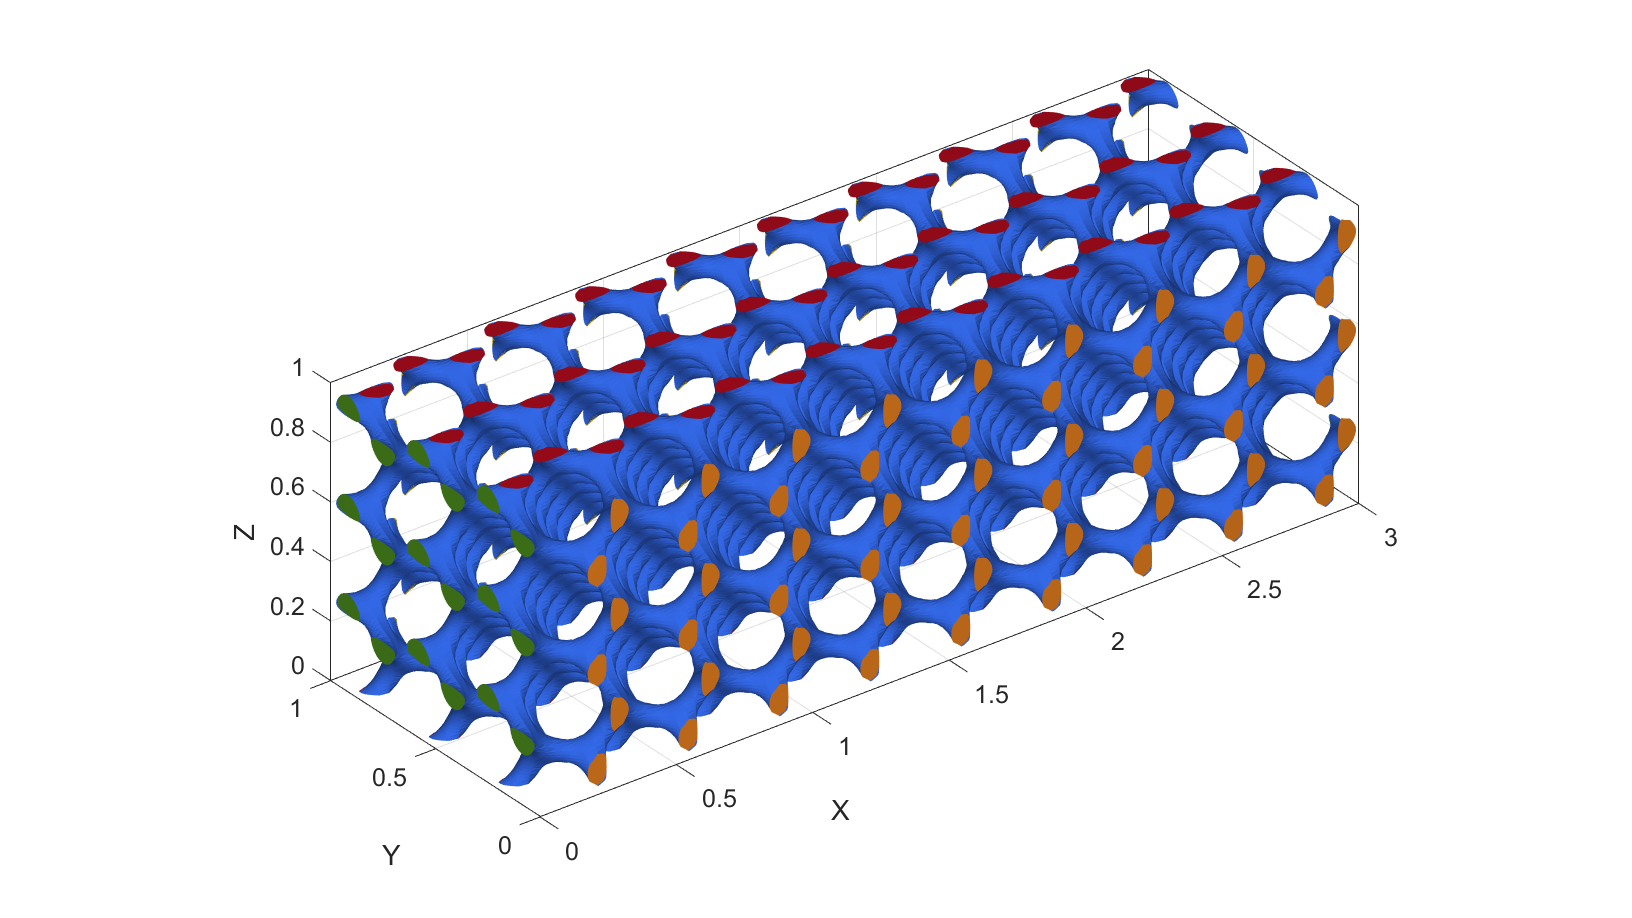

i = 1; % initialise i
nCols = 4;
nRows = 3;

for j = linspace(1,-1,10)
load

f = resultStruct.f; v = resultStruct.v; c = resultStruct.c;

% cFigure;
subplot(nRows, nCols, i);

% title('Face labelling');
hp1 = gpatch(f,v,c,'none', 1); 
hp1.FaceColor = 'Flat';
colormap(gca,gjet(6)); 
axisGeom(gca,fontSize); camlight headlight;

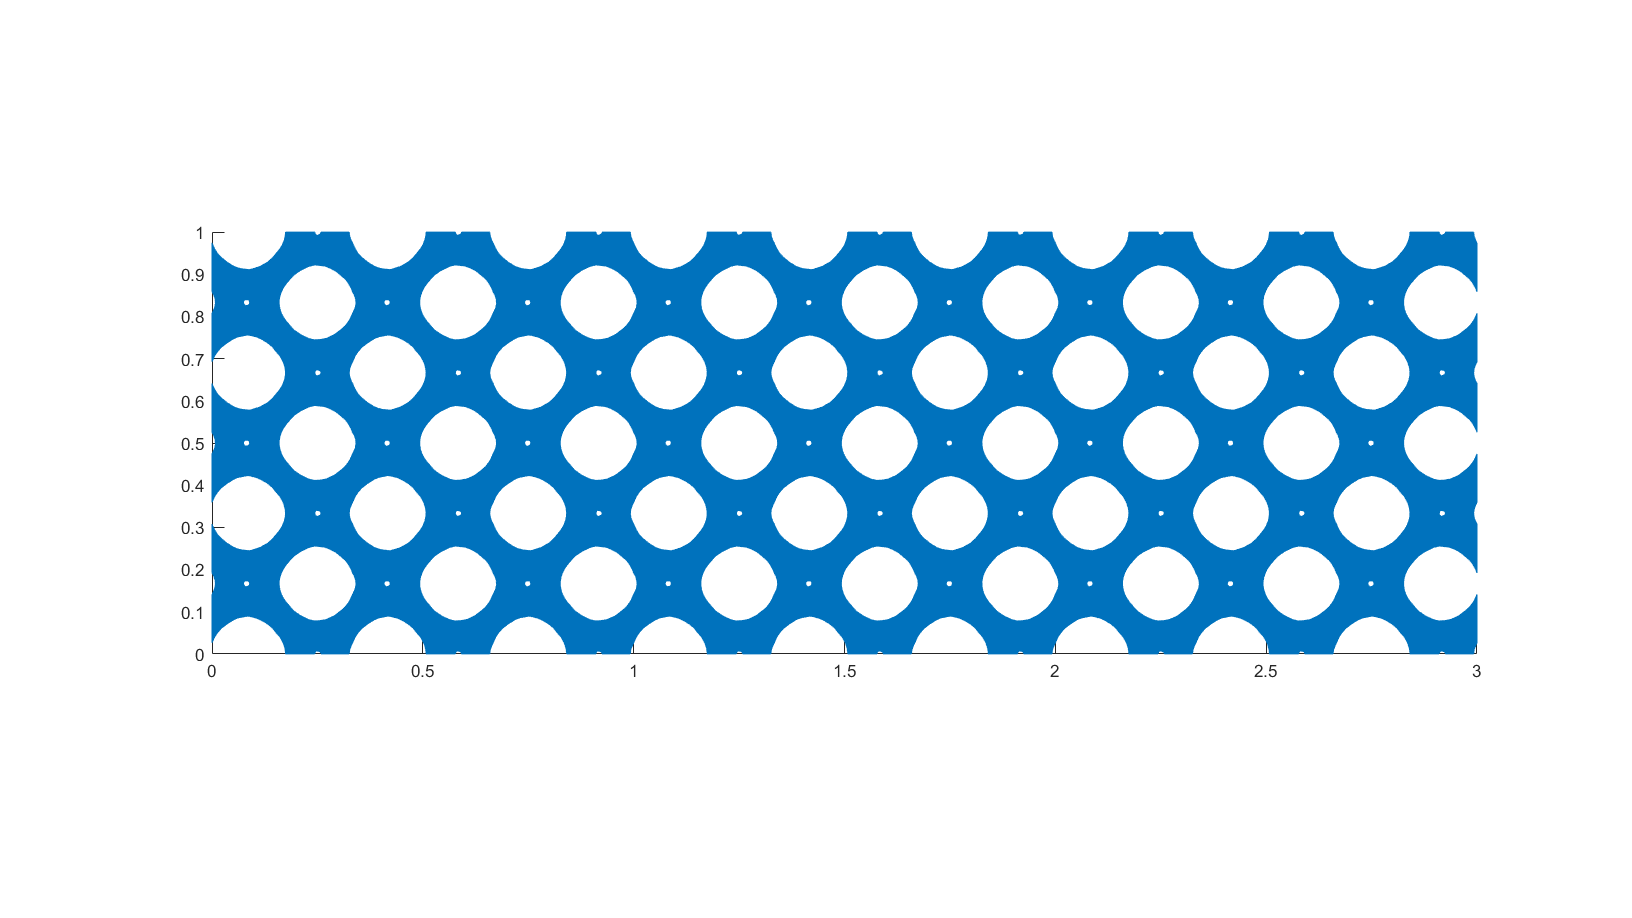


cFigure;
% title('Orthographic Projection');
% Create the patch with uniform color
hp2 = gpatch(f, v, 'none', 1);
hp2.FaceColor = [0 0.4470 0.7410];
hp2.EdgeColor = [0 0.4470 0.7410];
axis equal;
xlim([min(v(:,1)), max(v(:,1))]) % Adjust x-axis limits to your data range
ylim([min(v(:,2)), max(v(:,2))]) % Adjust y-axis limits to your data range

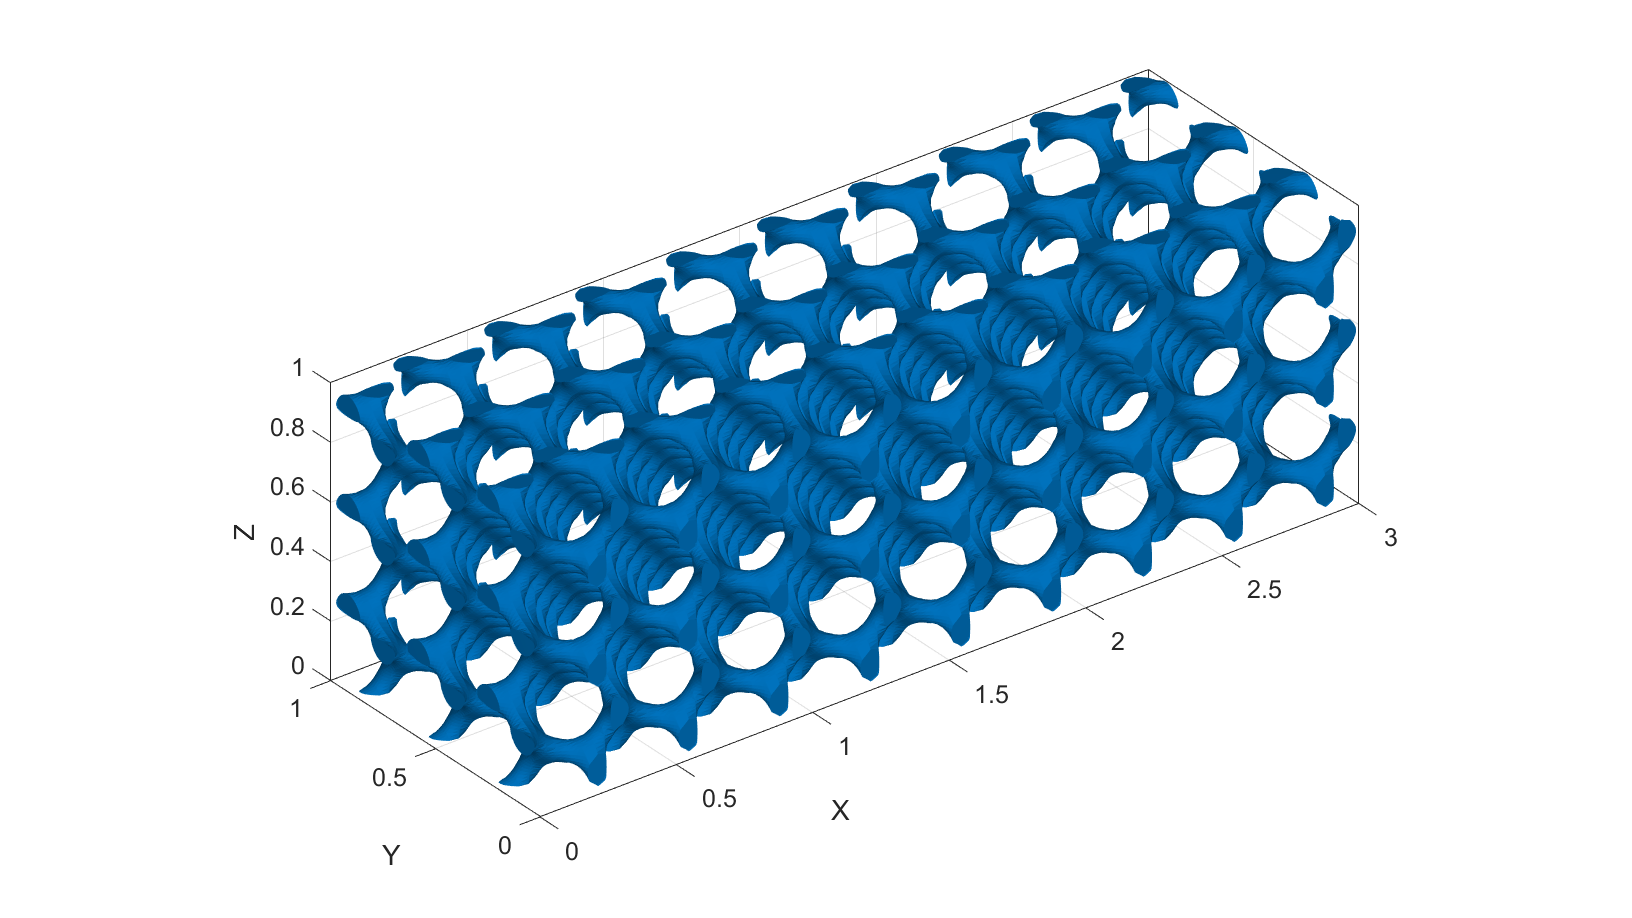


cFigure;
% title('Iso-surface');
hp3 = gpatch(f,v,c,'none', 1); 
hp3.FaceColor = [0 0.4470 0.7410];
% hp3.EdgeColor = 'k';
colormap(gca,gjet(6)); 
axisGeom(gca,fontSize); camlight headlight;

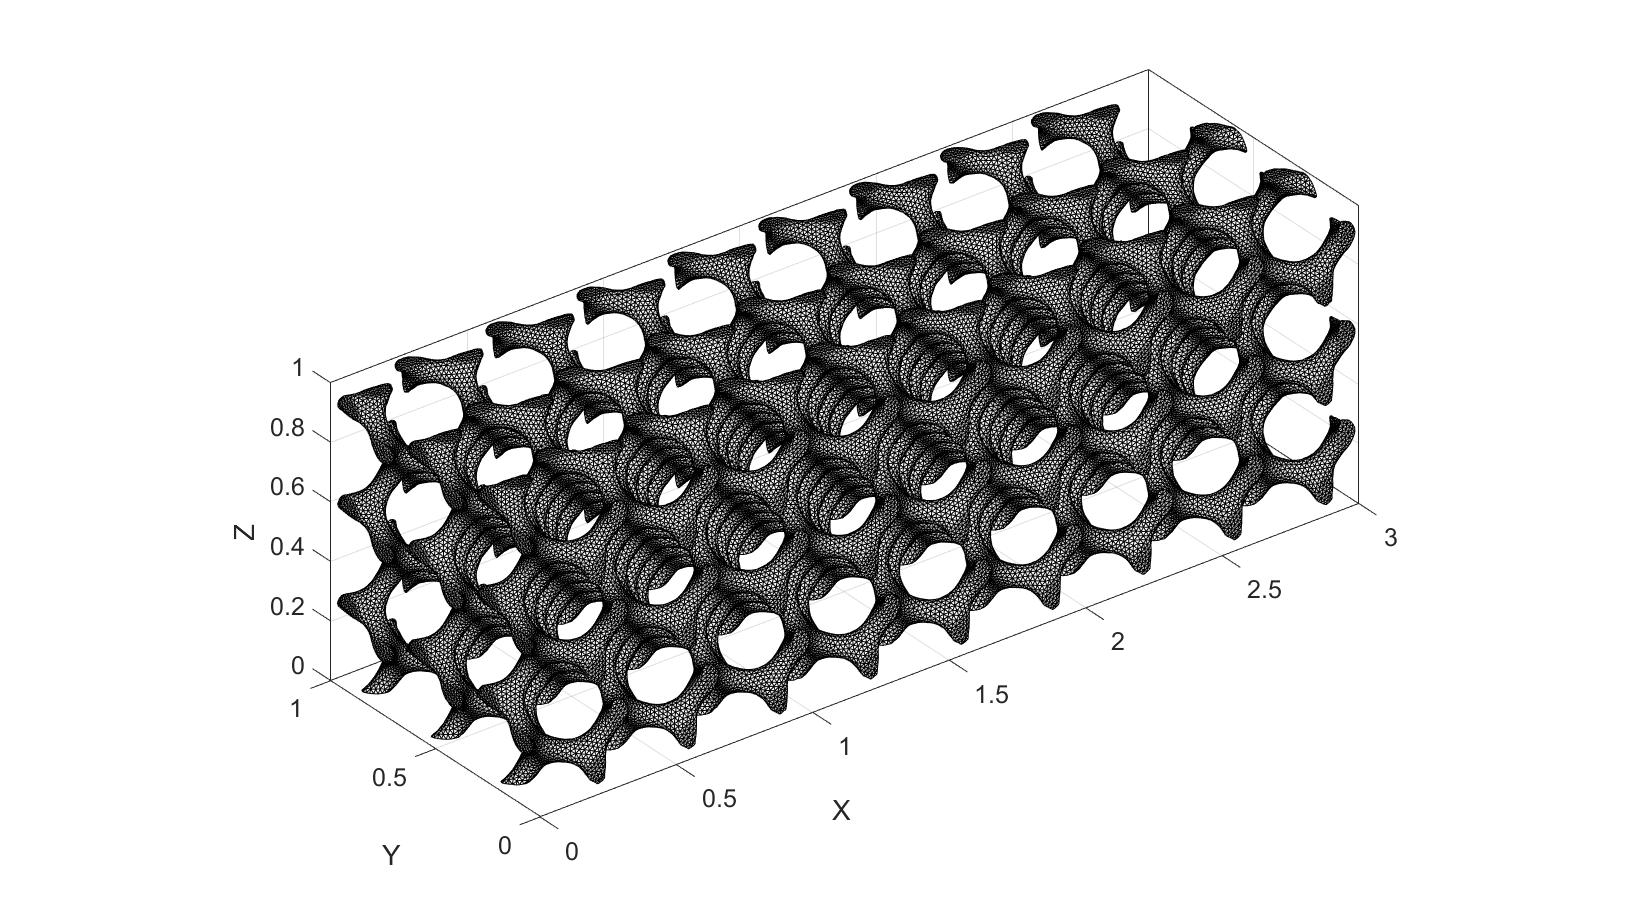

F = resultStruct.F; V = resultStruct.V;
cFigure; hold on;

if figureTitles
    title('Geogram remeshed','FontSize',fontSize);
end

gpatch(F,V,'w','k',1);
axisGeom(gca,fontSize);
camlight headlight;

meshOutput = resultStruct.meshOutput;
% meshView(meshOutput);
Fb=meshOutput.facesBoundary;
V=meshOutput.nodes;

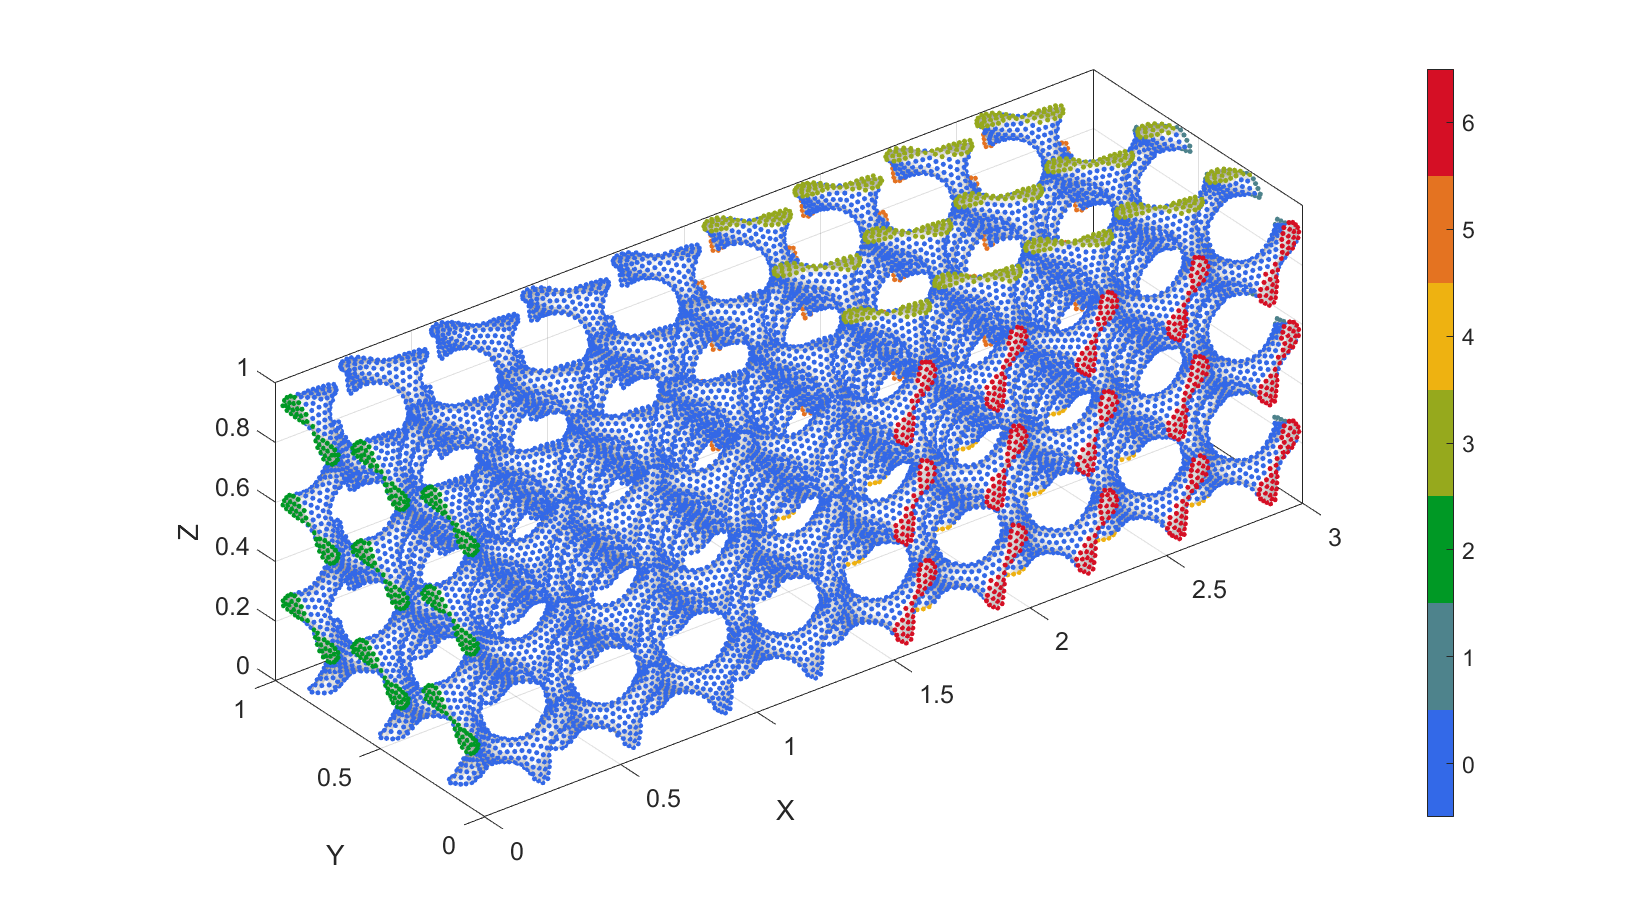

C_vertex = resultStruct.C_vertex;

hf=cFigure;

% title('Boundary Nodes','FontSize',fontSize);

xlabel('X','FontSize',fontSize); ylabel('Y','FontSize',fontSize); zlabel('Z','FontSize',fontSize);
hold on;

gpatch(Fb,V,'w','none',1);
scatterV(V,10,C_vertex,'filled');

axisGeom(gca,fontSize);
colormap gjet; icolorbar;
camlight headlight;

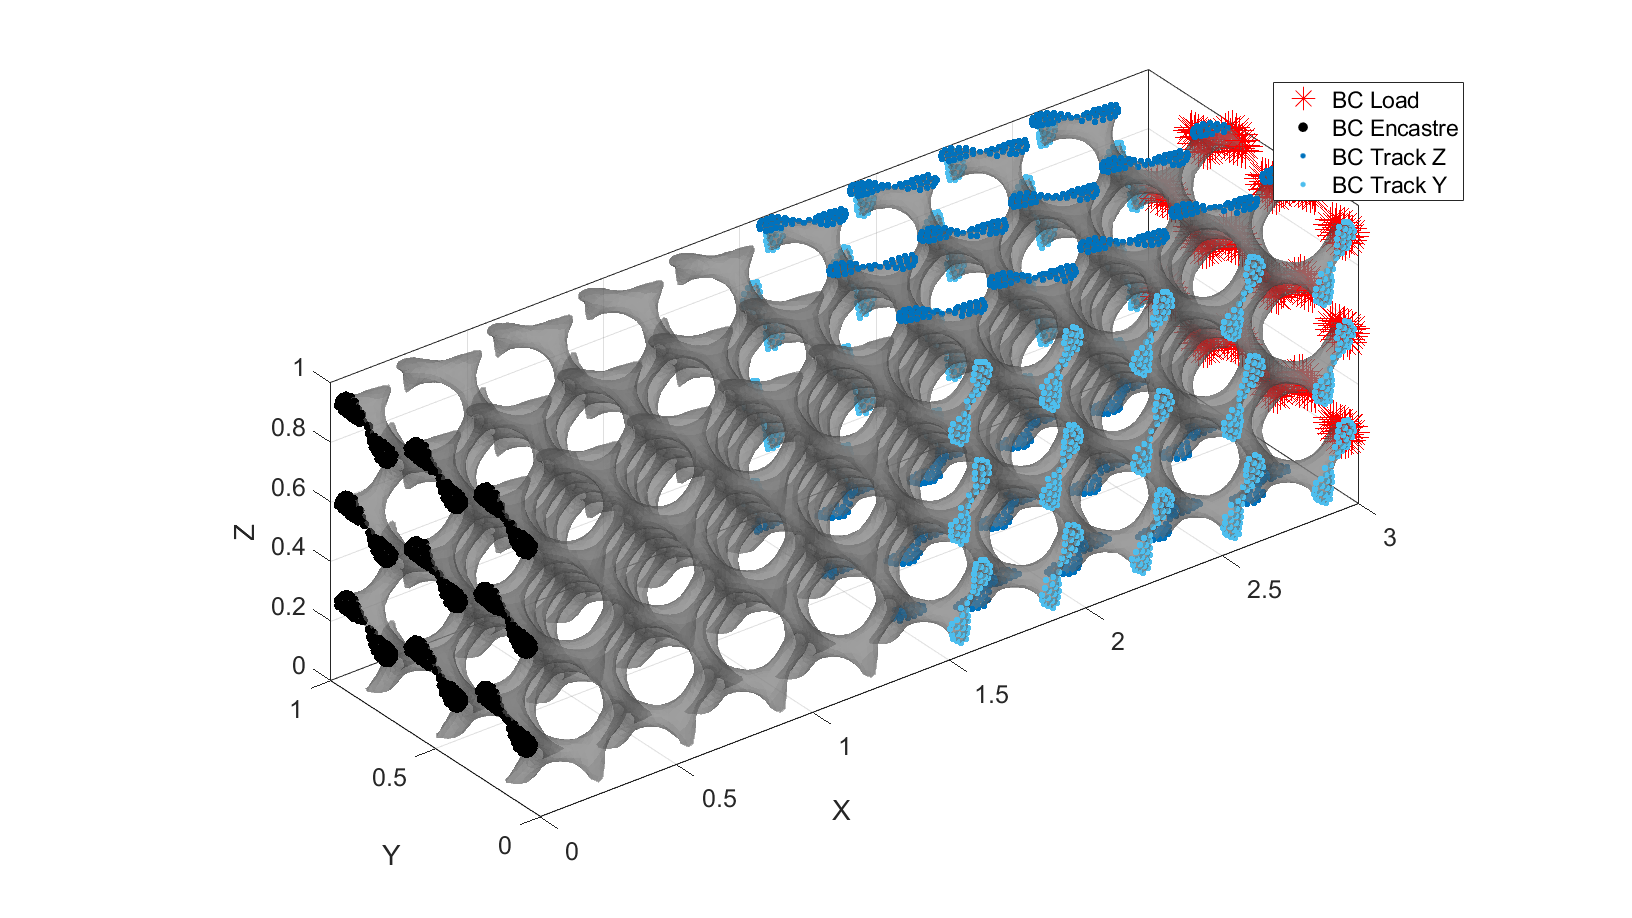

bcEncastreList = resultStruct.bcSets.bcEncastreList;
bcSetsbcLoadList = resultStruct.bcSets.bcLoadList;
bcTrackY = resultStruct.bcSets.bcTrackY;
bcTrackZ = resultStruct.bcSets.bcTrackZ;

hl=cFigure;
if figureTitles
    title('Boundary conditions','FontSize',fontSize);
end
xlabel('X','FontSize',fontSize); ylabel('Y','FontSize',fontSize); zlabel('Z','FontSize',fontSize);
hold on;
gpatch(Fb,V,'kw','none',0.5);

hl(1)=plotV(V(bcEncastreList,:),'r*','MarkerSize',markerSize);
hl(2)=plotV(V(bcLoadList,:),'k.','MarkerSize',markerSize);
hl(3)=plotV(V(bcTrackZ,:),'.','MarkerSize',markerSize/2, 'MarkerEdgeColor', blue);
hl(4)=plotV(V(bcTrackY,:),'c.','MarkerSize',markerSize/2, 'MarkerEdgeColor', cyan);
legend(hl,{'BC Load','BC Encastre','BC Track Z','BC Track Y'});

axisGeom(gca,fontSize);
camlight headlight;

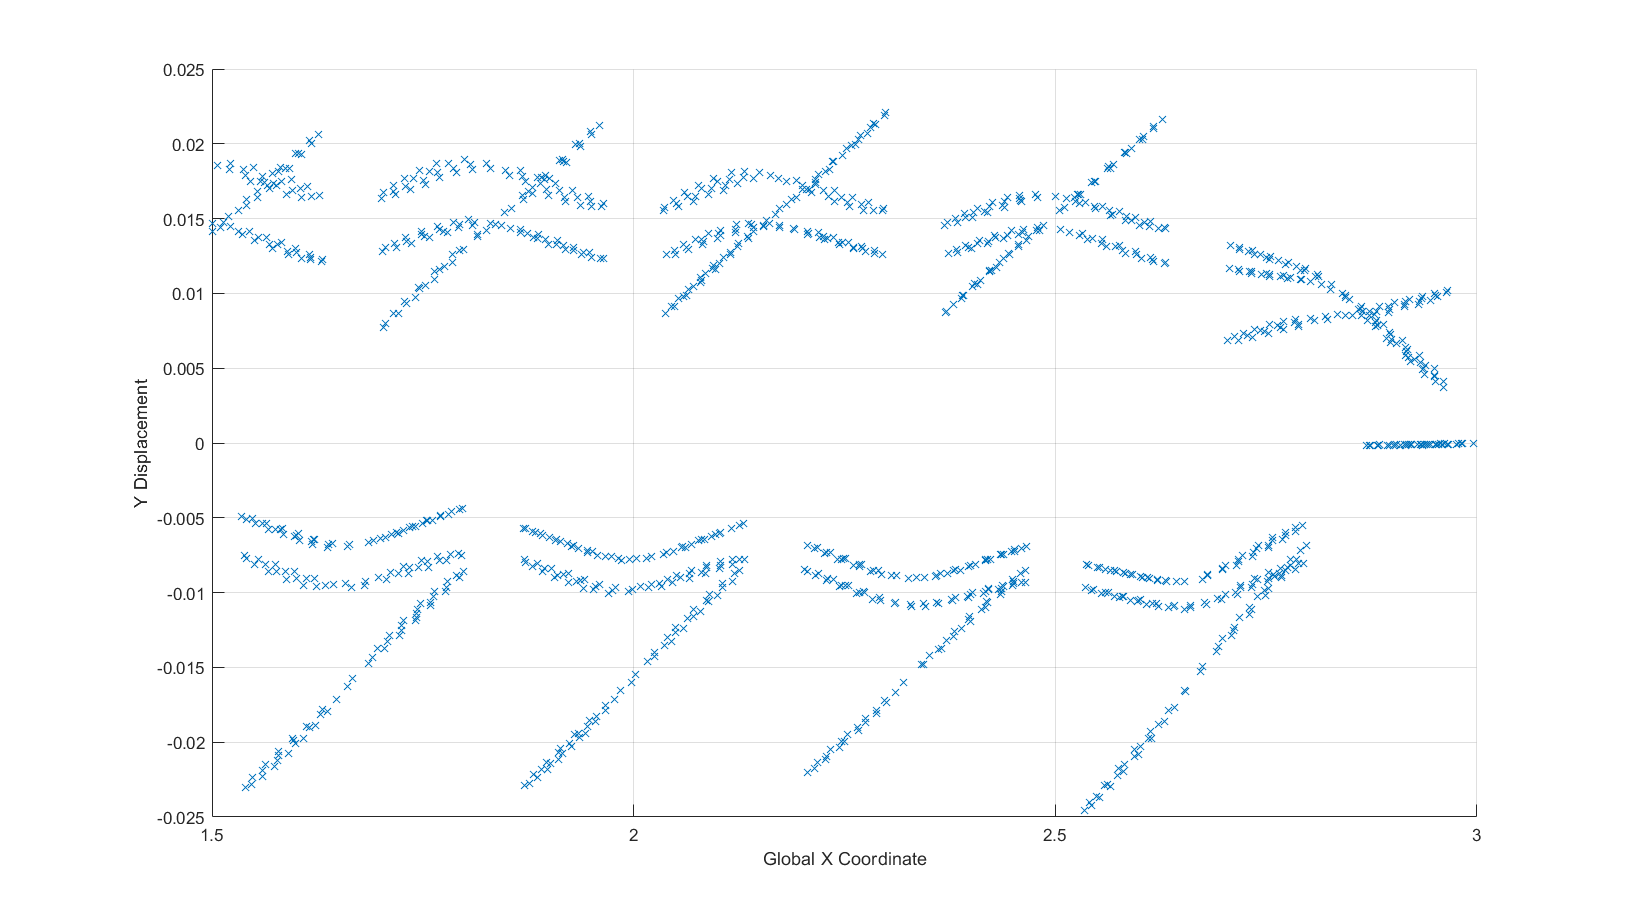

cFigure;
xz = resultStruct.xz; Uz = resultStruct.Uz;
scatter(xz, Uz, 'x', 'MarkerEdgeColor', blue);

xlabel('Global X Coordinate');
ylabel('Y Displacement');
grid on;

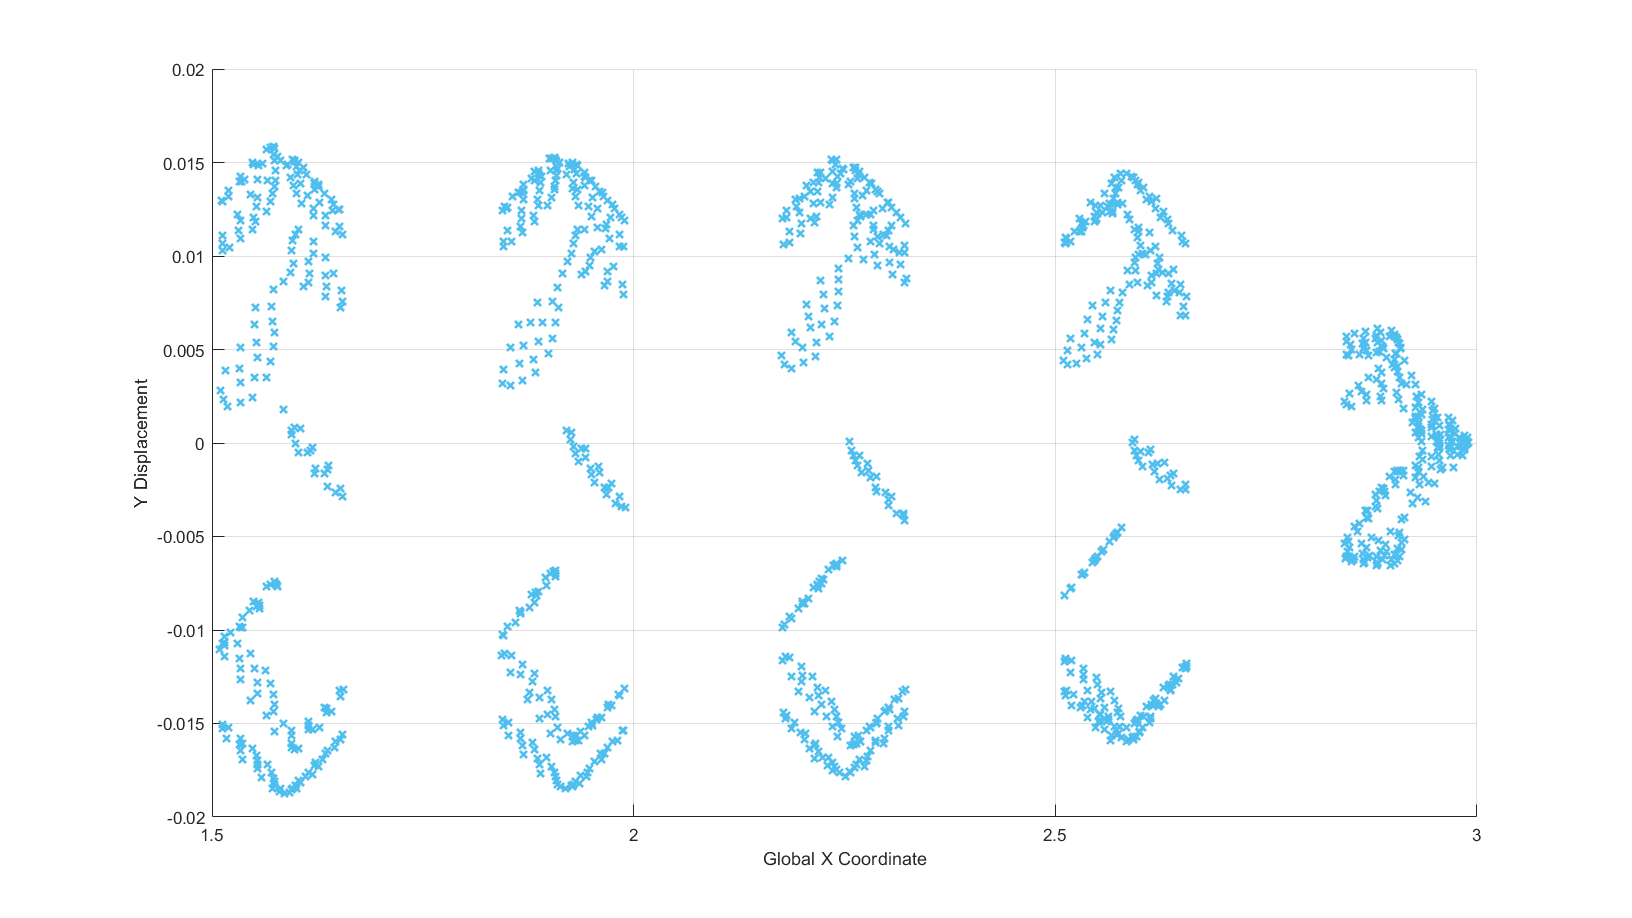

cFigure;
xy = resultStruct.xy; Uy = resultStruct.Uy;
scatter(xy, Uy, 'x', 'MarkerEdgeColor', cyan, 'LineWidth', 1.5);

xlabel('Global X Coordinate');
ylabel('Y Displacement');
grid on;

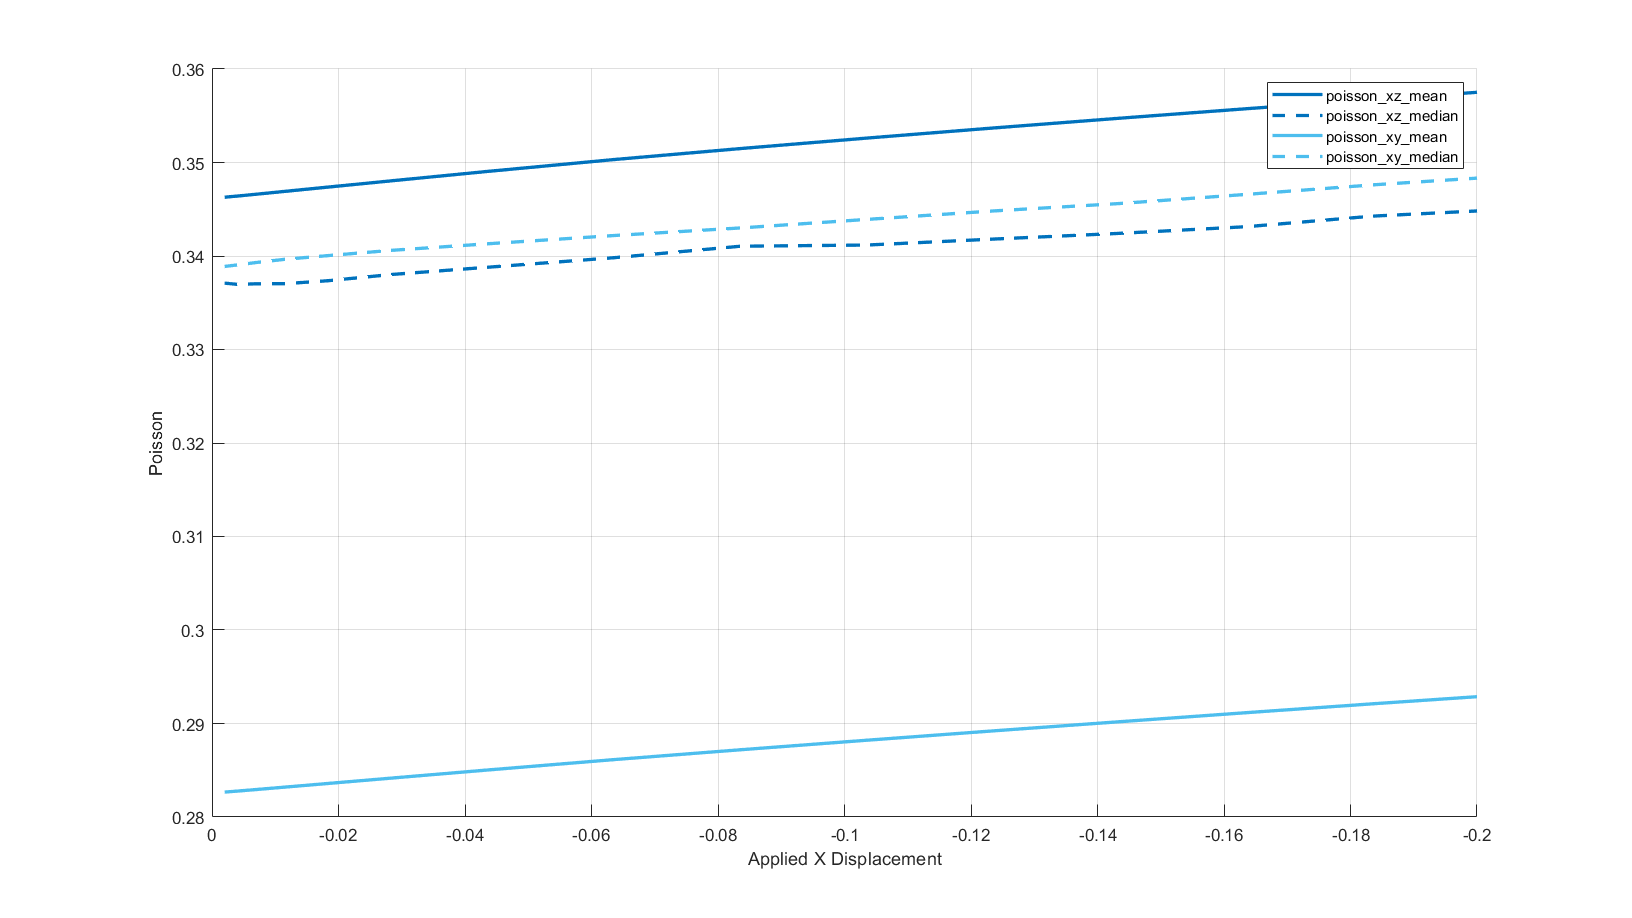

U_x = resultStruct.U_x;
poisson_xz_mean = resultStruct.poisson.poisson_xz_mean;
poisson_xz_median = resultStruct.poisson.poisson_xz_median;
poisson_xy_mean = resultStruct.poisson.poisson_xy_mean;
poisson_xy_median = resultStruct.poisson.poisson_xy_median;

cFigure;
hold on; grid on;

% Plot Poisson ratios for xz direction (using blue colors)
plot(U_x, poisson_xz_mean, '-', 'LineWidth', 2,'Color',blue);
plot(U_x, poisson_xz_median, '--', 'LineWidth', 2,'Color',blue);
% plot(U_x, poisson_xz_max, 'b:', 'LineWidth', 2);

% Plot Poisson ratios for xy direction (using red colors)
plot(U_x, poisson_xy_mean, '-', 'LineWidth', 2,'Color',cyan);
plot(U_x, poisson_xy_median, '--', 'LineWidth', 2,'Color',cyan);
% plot(U_x, poisson_xy_max, 'r:', 'LineWidth', 2);

ylabel("Poisson", "FontName", "Helvetica", "FontAngle", "normal", "FontWeight", "normal")
xlabel("Applied X Displacement", "FontName", "Helvetica", "FontAngle", "normal", "FontWeight", "normal")

legend({'poisson\_xz\_mean', 'poisson\_xz\_median', ...
        'poisson\_xy\_mean', 'poisson\_xy\_median'}, ...
       'Location', 'northeast');

set(gca, 'XDir', 'reverse');

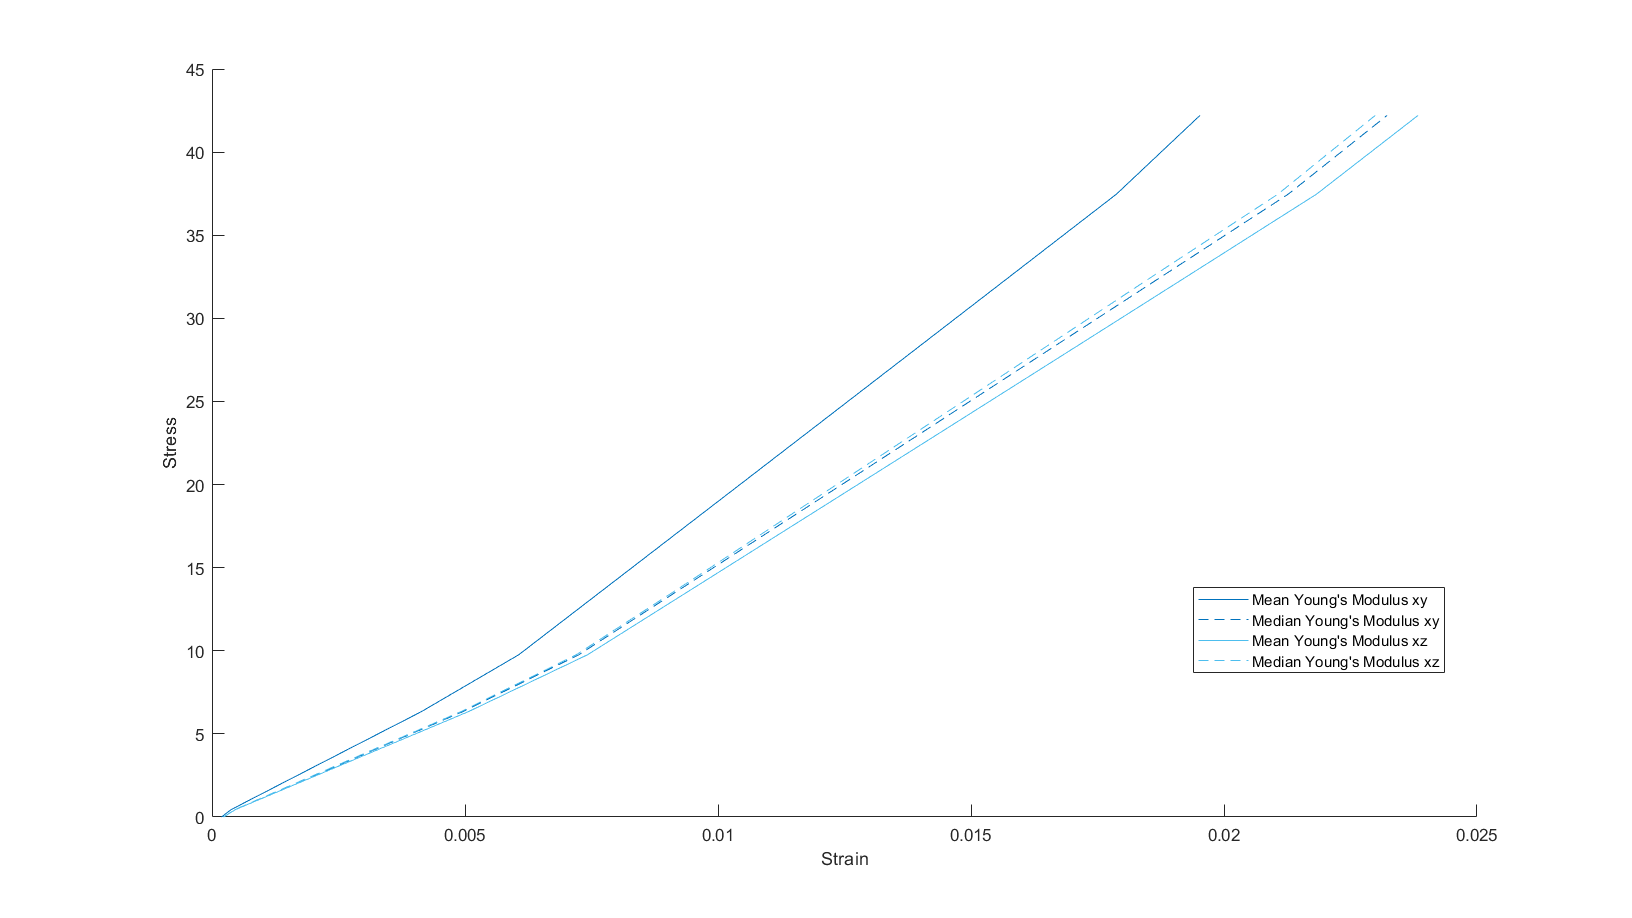

strain_y_mean = resultStruct.strain.strain_y_mean;
strain_y_median = resultStruct.strain.strain_y_median;
strain_z_mean = resultStruct.strain.strain_z_mean;
strain_z_median = resultStruct.strain.strain_z_median;
stress = resultStruct.stress;

cFigure;
hold on; grid on;
plot(abs(strain_y_mean),stress,'-','Color',blue);
plot(abs(strain_y_median),stress,'--','Color',blue);
plot(abs(strain_z_mean),stress,'-','Color',cyan);
plot(abs(strain_z_median),stress,'--','Color',cyan);


legend('Mean Young''s Modulus xy', 'Median Young''s Modulus xy', 'Mean Young''s Modulus xz', 'Median Young''s Modulus xz','Location','best');

xlabel("Strain", "FontName", "Helvetica", "FontAngle", "normal", "FontWeight", "normal")
ylabel("Stress", "FontName", "Helvetica", "FontAngle", "normal", "FontWeight", "normal")


i = i + 1;
end

poisson_xz_mean(i) = resultStruct.poisson_xz_mean;
poisson_xz_median(i) = resultStruct.poisson_xz_median;
poisson_xy_mean(i) = resultStruct.poisson_xy_mean;
poisson_xy_median(i) = resultStruct.poisson_xy_median;